addpath('../build/Matlab/');

Display

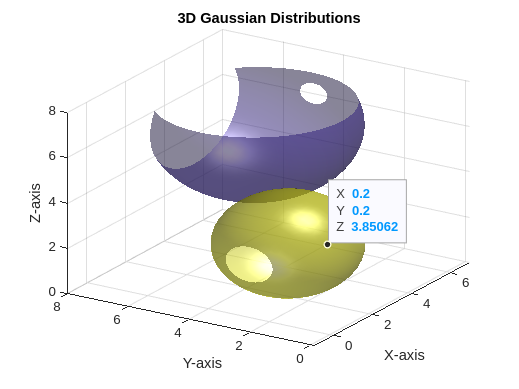

% Define the means and covariance matrices
mu1 = [1; 2; 3];
mu2 = [4; 5; 6];
cov1 = eye(3);       % Identity matrix as covariance matrix for first Gaussian
cov2 = 2 * eye(3);   % Scaled identity matrix for the second Gaussian

% Create a grid over which to calculate the Gaussian distributions
[x, y, z] = meshgrid(-1:0.2:7, -1:0.2:7, -1:0.2:7);

% Convert the grid to a format suitable for mvnpdf
xyz = [x(:) y(:) z(:)];

% Calculate the Gaussian distributions over the grid
gauss1 = mvnpdf(xyz, mu1', cov1);
gauss2 = mvnpdf(xyz, mu2', cov2);

% Reshape the distributions back to grid form for plotting
gauss1 = reshape(gauss1, size(x));
gauss2 = reshape(gauss2, size(x));

% Plot the two distributions using isosurfaces
figure;
isosurface(x, y, z, gauss1, max(gauss1(:)) * 0.1); % Adjust contour level for visibility
hold on;
isosurface(x, y, z, gauss2, max(gauss2(:)) * 0.1); % Adjust contour level for visibility

% Add labels and title
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Gaussian Distributions');
grid on;
alpha(0.5); % Make surfaces slightly transparent for better visualization
hold off;

Compare